# Actividad #5

**Organización de Código y Uso de Librerías en MATLAB**

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

## Descripción:

En esta práctica se promueve el uso de programación estructurada en MATLAB mediante la creación de una carpeta `./src` para organizar funciones reutilizables como bibliotecas. Además, se automatiza el respaldo del proyecto usando funciones personalizadas, se implementa la generación de señales senoidales, y se visualizan los resultados. Esta estructura permite mantener el código limpio, modular y escalable.

## Objetivos:

- Aplicar principios de programación estructurada mediante la organización del código en una carpeta `src`.

- Automatizar el respaldo del entorno de trabajo con una función personalizada (`git_sse`).

- Reutilizar funciones externas para la generación de señales senoidales.

- Visualizar y analizar señales con diferentes parámetros usando herramientas gráficas de MATLAB.

## **Copia la actividad en tu respaldo**

% Configuracion de carpeta ./src para librerias
addpath(genpath('./src'));

% Definir rutas
miRespaldo = 'C:\Desktop\SSE_vic';  %<========
repositorio = 'C:\Desktop\SSE\2025';%<========

if false
    % repositorio -> respaldo
    git_sse(miRespaldo)
else
    % Mombre de la carpeta de la Actividad en el repositorio
    nombreCarpeta = string(split(cd, filesep));
    nombreCarpeta = nombreCarpeta(end) % Nombre de la carpeta
    % Regresar al repositorio
    cd(fullfile(repositorio,nombreCarpeta));
end

nombreCarpeta = "ACTIVIDAD5"

## Desarrollo de la Actividad

#### Paso 1: Borrar variables en el workspace y limpiar command window

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

#### Paso 2: Crear un codigo basico

% Parámetros
f = 10;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2
T = 0.25;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 620;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs);
y2 = senal_senoidal(f,A2,fase2,T,fs);

#### Paso 3: Mostrar resultados con plot

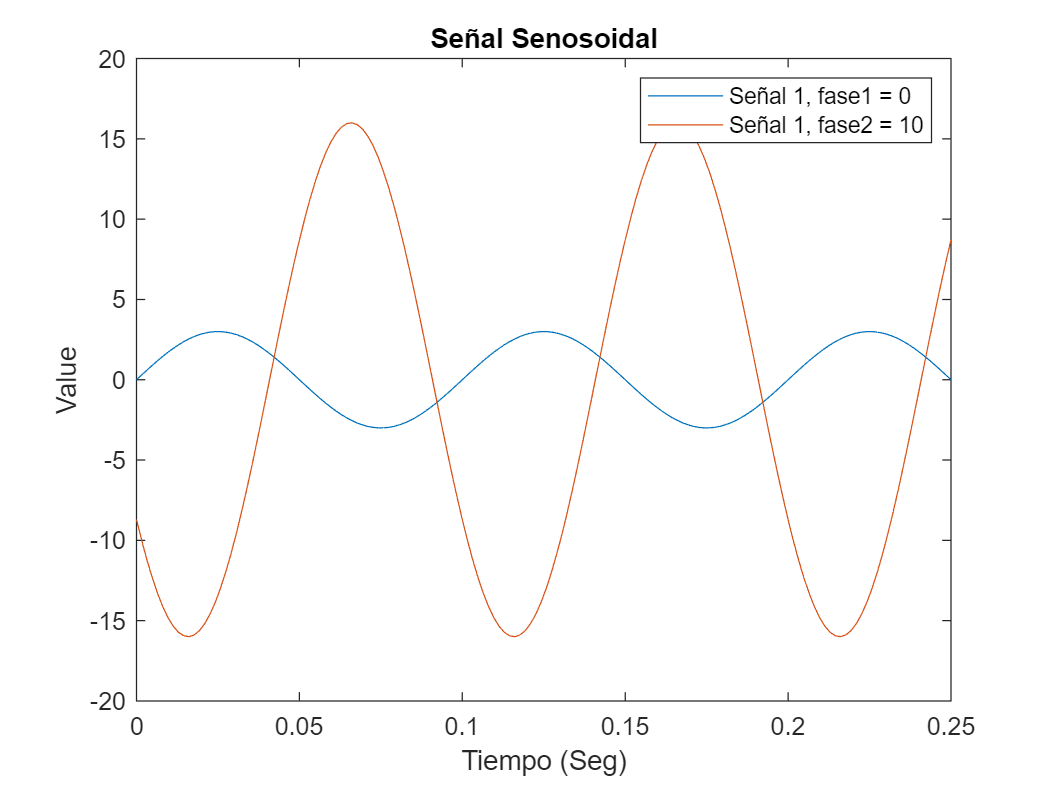

t = 0:1/fs:T;
figure
plot(t,y1) %Señal 1
hold on
plot(t,y2) %Señal 2
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10")